% Assuming the CIR data is stored in a text file with the format:
% real_value_1, imaginary_value_1
% real_value_2, imaginary_value_2
% ...
% Load the CIR data from the file
filename = '.\Data\Metal_Reflection2\CIR.txt'; % Replace with the actual file path
data = load(filename);

% Extract the real and imaginary parts
real_part = data(:, 1);   % First column is the real part
imag_part = data(:, 2);   % Second column is the imaginary part

% Compute the magnitude of the CIR (optional, if you want to plot magnitude)
magnitude = sqrt(real_part.^2 + imag_part.^2);

% Plot the CIR in the complex plane (real vs imaginary)
figure;
% subplot(2,1,1);
% plot(real_part, imag_part, 'o');
% title('CIR in the Complex Plane');
% xlabel('Real Part');
% ylabel('Imaginary Part');
% grid on;

% Plot the magnitude of the CIR
% subplot(2,1,2);
plot(magnitude,'b');
title('Magnitude of CIR', 'FontSize', 16);
xlabel('Sample Index', 'FontSize', 14);
ylabel('Magnitude', 'FontSize', 14);
grid on;

figure;
plot(magnitude);
title('Magnitude of CIR');
xlabel('Sample Index');
ylabel('Magnitude');

filename = '.\Data\Calibration\new_STS0_3.txt'; % Replace with the actual file path
STS0_data = load(filename);

% Extract the real and imaginary parts
STS0_real_part = STS0_data(:, 1);   % First column is the real part
STS0_imag_part = STS0_data(:, 2);   % Second column is the imaginary part

% Compute the magnitude of the CIR (optional, if you want to plot magnitude)
STS0_magnitude = sqrt(STS0_real_part.^2 + STS0_imag_part.^2);

% Find the peak index (maximum magnitude)
[~, peak_index_STS0] = max(STS0_magnitude);


% Compute the phase at the peak index
STS0_phase_peak = atan2(STS0_imag_part(peak_index_STS0), STS0_real_part(peak_index_STS0));

% Plot the CIR in the complex plane (real vs imaginary)
figure;
subplot(2,1,1);
plot(STS0_real_part, STS0_imag_part, 'o');
title('STS0 CIR in the Complex Plane');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;

% Plot the magnitude of the CIR
subplot(2,1,2);
plot(STS0_magnitude);
title('Magnitude of STS0 CIR');
xlabel('Sample Index');
ylabel('Magnitude');
grid on;


filename = '.\Data\Calibration\new_STS1_3.txt'; % Replace with the actual file path
STS1_data = load(filename);

% Extract the real and imaginary parts
STS1_real_part = STS1_data(:, 1);   % First column is the real part
STS1_imag_part = STS1_data(:, 2);   % Second column is the imaginary part

% Compute the magnitude of the CIR (optional, if you want to plot magnitude)
STS1_magnitude = sqrt(STS1_real_part.^2 + STS1_imag_part.^2);

% Find the peak index (maximum magnitude)
[~, peak_index_STS1] = max(STS1_magnitude);

% Compute the phase at the peak index
STS1_phase_peak = atan2(STS1_imag_part(peak_index_STS1), STS1_real_part(peak_index_STS1));

% Plot the CIR in the complex plane (real vs imaginary)
figure;
subplot(2,1,1);
plot(STS1_real_part, STS1_imag_part, 'o');
title('STS1 CIR in the Complex Plane');
xlabel('Real Part');
ylabel('Imaginary Part');
grid on;

% Plot the magnitude of the CIR
subplot(2,1,2);
plot(STS1_magnitude);
title('Magnitude of STS1 CIR');
xlabel('Sample Index');
ylabel('Magnitude');
grid on;

phase_offset = 0.7;
% 0.8270, 0.8046 , 0.8644

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/6.5e9;
antennaSpacing = lambda/2;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=6.5e9;

phase_difference = STS1_phase_peak - STS0_phase_peak - phase_offset;

phase_difference = mod(phase_difference + pi, 2*pi) - pi;

theta_radians = asin(phase_difference * c / (2 * pi * antennaSpacing * frequency));
theta_degrees = rad2deg(theta_radians)

% % Display phase difference
% fprintf('Peak phase STS0: %.2f degrees\n', rad2deg(STS0_phase_peak));
% fprintf('Peak phase STS1: %.2f degrees\n', rad2deg(STS1_phase_peak));
% fprintf('Phase difference: %.2f degrees\n', phase_difference_deg);


% 文件名
filename = '.\Data\AOA_drift.txt';

% 打开文件
fid = fopen(filename, 'r');

% 初始化存储
pdoa_values = [];
degree_values = [];

% 逐行读取
while ~feof(fid)
    line = fgetl(fid);  % 读取一行
    
    % 使用正则表达式提取数值
    tokens = regexp(line, 'PDOA val = ([\-\d\.]+), Degrees = ([\-\d\.]+)', 'tokens');
    
    if ~isempty(tokens)
        % 提取值并转换为数字
        pdoa_val = str2double(tokens{1}{1});
        degree_val = str2double(tokens{1}{2});
        
        % 存入数组
        pdoa_values(end+1, 1) = pdoa_val;
        degree_values(end+1, 1) = degree_val;
    end
end

% 关闭文件
fclose(fid);

time = 1:length(pdoa_values);
figure;

subplot(2,1,1);
plot(time, pdoa_values, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Sample Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Sample Index)');
ylabel('Angle (Degrees)');
grid on;

text(time, pdoa_values, string(pdoa_values), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(time, degree_values, string(degree_values), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

function delta_d = calcPathDifference(d_direct, d1, d2)
    % calcPathDifference
    % 输入：
    %   d_direct：直射路径长度
    %   d1：反射路径的第一段长度（发射到反射点）
    %   d2：反射路径的第二段长度（反射点到接收点）
    %
    % 输出：
    %   delta_d：反射路径比直射路径多走的距离
    
    % 计算反射路径长度
    d_reflect = d1 + d2;
    
    % 计算距离差
    delta_d = d_reflect - d_direct;
    
    % 显示结果
    fprintf('反射路径与直射路径的距离差为 %.4f\n', delta_d);
end

calcPathDifference(2.115,1.720,1.227);

% 两个点的坐标
x1 = -0.8;  y1 = 1.9;  % 发射端 (Tx)
x2 =  0.8;  y2 = 1.9;  % 接收端 (Rx)

% 计算距离
distance = sqrt((x2 - x1)^2 + (y2 - y1)^2);

% 输出结果
fprintf('两点之间的距离为 %.4f\n', distance);

4.1231 - 1.6


% 定义坐标
x1 = -3.2;  y1 = -3.8;  % 发射端 (Tx)
x2 =  3.2;  y2 = -3.8;  % 接收端 (Rx)

% 计算 Tx 关于 x 轴的镜像点
x1_mirror = x1;
y1_mirror = -y1; % y 轴取反

% 计算路径长度
direct_path = sqrt((x2 - x1)^2 + (y2 - y1)^2); % 直达路径
reflected_path = sqrt((x2 - x1_mirror)^2 + (y2 - y1_mirror)^2); % 镜像路径
path_diff = reflected_path - direct_path; % 路径差

% 显示路径差
fprintf('直达路径长度：%.4f m\n', direct_path);
fprintf('反射路径长度：%.4f m\n', reflected_path);
fprintf('路径差：%.4f m\n', path_diff);

% 创建图形
figure; hold on; grid on;
axis equal;
xlabel('X-axis (m)'); ylabel('Y-axis (m)');
title('直达路径 & 反射路径');

% 绘制墙面 (x 轴和原点)
plot([-2, 2], [0, 0], 'k', 'LineWidth', 2); % 画 x 轴作为墙面
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); % 原点

% 绘制发射端和接收端
plot(x1, y1, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Tx
plot(x2, y2, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); % Rx
text(x1, y1, '  Tx', 'FontSize', 12, 'Color', 'r', 'VerticalAlignment', 'bottom');
text(x2, y2, '  Rx', 'FontSize', 12, 'Color', 'b', 'VerticalAlignment', 'bottom');

% 画直达路径
plot([x1, x2], [y1, y2], 'r--', 'LineWidth', 1.5);
text(mean([x1, x2]), mean([y1, y2]), sprintf('  直达路径\n  %.3f m', direct_path), 'FontSize', 10, 'Color', 'r');

% 画反射路径
plot([x1_mirror, x2], [y1_mirror, y2], 'b-.', 'LineWidth', 1.5);
plot(x1_mirror, y1_mirror, 'go', 'MarkerSize', 6, 'MarkerFaceColor', 'g'); % 镜像点
text(x1_mirror, y1_mirror, '  镜像点', 'FontSize', 10, 'Color', 'g', 'VerticalAlignment', 'top');
text(mean([x1_mirror, x2]), mean([y1_mirror, y2]), ...
    sprintf('  反射路径\n  %.3f m', reflected_path), 'FontSize', 10, 'Color', 'b');

% 显示路径差信息
text(0, -2.4, sprintf('路径差：%.4f m', path_diff), 'FontSize', 11, 'FontWeight', 'bold', 'Color', 'm');

legend({'墙面 (x轴)', '原点 (0,0)', '发射端 Tx', '接收端 Rx', '直达路径', '反射路径', '镜像点'}, ...
       'Location', 'SouthOutside', 'NumColumns', 2);

hold off;

% 论文中使用
% 定义坐标
x1 = -1.6;  y1 = -2.4;  % 发射端 (Tx)
x2 = 1.6;  y2 = -2.4;  % 接收端 (Rx)

% 计算 Tx 关于 x 轴的镜像点
x1_mirror = x1;
y1_mirror = -y1; % y 轴取反

% 计算路径长度
direct_path = sqrt((x2 - x1)^2 + (y2 - y1)^2); % 直达路径
reflected_path = sqrt((x2 - x1_mirror)^2 + (y2 - y1_mirror)^2); % 镜像路径
path_diff = reflected_path - direct_path; % 路径差

% 显示路径差
fprintf('直达路径长度：%.4f m\n', direct_path);
fprintf('反射路径长度：%.4f m\n', reflected_path);
fprintf('路径差：%.4f m\n', path_diff);

% 创建图形
figure; hold on; grid on;
axis equal;
set(gca, 'FontSize', 16); % 坐标轴刻度字体加大
xlabel('X-axis (m)', 'FontSize', 18); 
ylabel('Y-axis (m)', 'FontSize', 18);
title('直达路径 & 反射路径', 'FontSize', 20, 'FontWeight', 'bold');

% 绘制墙面 (x 轴和原点)
plot([-2, 2], [0, 0], 'k', 'LineWidth', 2); % 画 x 轴作为墙面
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); % 原点

% 绘制发射端和接收端
plot(x1, y1, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Tx
plot(x2, y2, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Rx
text(x1, y1, '  Tx', 'FontSize', 16, 'Color', 'r', 'VerticalAlignment', 'bottom');
text(x2, y2, '  Rx', 'FontSize', 16, 'Color', 'b', 'VerticalAlignment', 'bottom');

% 画直达路径
plot([x1, x2], [y1, y2], 'r--', 'LineWidth', 2);
text(mean([x1, x2]), mean([y1, y2]), ...
    sprintf(' 直达路径\n %.3f m', direct_path), 'FontSize', 14, 'Color', 'r');

% 画反射路径
plot([x1_mirror, x2], [y1_mirror, y2], 'b-.', 'LineWidth', 2);
plot(x1_mirror, y1_mirror, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % 镜像点
text(x1_mirror, y1_mirror, '  镜像点', 'FontSize', 14, 'Color', 'g', 'VerticalAlignment', 'top');
text(mean([x1_mirror, x2]), mean([y1_mirror, y2]), ...
    sprintf(' 反射路径\n %.3f m', reflected_path), 'FontSize', 14, 'Color', 'b');

% 显示路径差信息
text(0, -2.4, sprintf('路径差：%.4f m', path_diff), ...
    'FontSize', 16, 'FontWeight', 'bold', 'Color', 'm');

legend({'墙面 (x轴)', '原点 (0,0)', '发射端 Tx', '接收端 Rx', ...
        '直达路径', '反射路径', '镜像点'}, ...
       'Location', 'SouthOutside', 'NumColumns', 2, 'FontSize', 14);

hold off;

% 定义坐标
x1 = 2;  y1 = -2.4;  % 发射端 (Tx)
x2 = -2;  y2 = -2.4;  % 接收端 (Rx)

% 镜像点（Tx 关于 x轴镜像）
x1_mirror = x1;
y1_mirror = -y1;

% 路径长度
direct_path = sqrt((x2 - x1)^2 + (y2 - y1)^2);
reflected_path = sqrt((x2 - x1_mirror)^2 + (y2 - y1_mirror)^2);
path_diff = reflected_path - direct_path;

% 计算镜像点到Rx连线与x轴的交点（反射点）
% 线段：镜像点(x1_mirror, y1_mirror) 到 Rx(x2, y2)
% 解直线方程: y = kx + b, 使 y = 0，求x，即 x = -b/k
k = (y2 - y1_mirror) / (x2 - x1_mirror); % 斜率
b = y2 - k * x2;
x_reflect = -b / k;
y_reflect = 0; % 在墙面上

% 打印路径信息
fprintf('直达路径长度：%.4f m\n', direct_path);
fprintf('反射路径长度：%.4f m\n', reflected_path);
fprintf('路径差：%.4f m\n', path_diff);

% 绘图开始
figure; hold on; grid on; axis equal;
set(gca, 'FontSize', 20);
xlabel('X-axis (m)', 'FontSize', 22); 
ylabel('Y-axis (m)', 'FontSize', 22);
title('直达路径 & 反射路径', 'FontSize', 24, 'FontWeight', 'bold');

% 画墙面 (x轴) 和原点
plot([-2.5, 2.5], [0, 0], 'k', 'LineWidth', 2);
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% 画关键点
plot(x1, y1, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % Tx
plot(x2, y2, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b'); % Rx
plot(x1_mirror, y1_mirror, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % 镜像点
plot(x_reflect, y_reflect, 'mo', 'MarkerSize', 10, 'MarkerFaceColor', 'm'); % 反射点

% 标签文字
text(x1, y1, '  Tx', 'FontSize', 20, 'VerticalAlignment', 'bottom');
text(x2, y2, '  Rx', 'FontSize', 20, 'VerticalAlignment', 'bottom');
text(x1_mirror, y1_mirror, '  镜像点', 'FontSize', 18, 'VerticalAlignment', 'top');
text(x_reflect, y_reflect, '  反射点', 'FontSize', 18, 'VerticalAlignment', 'top');

% 直达路径
plot([x1, x2], [y1, y2], 'r--', 'LineWidth', 2);
text(mean([x1, x2]), mean([y1, y2]), ...
    sprintf('直达路径\n%.3f m', direct_path), 'FontSize', 18, 'Color', 'k');

% 反射路径（Tx -> 反射点 -> Rx）
plot([x1, x_reflect], [y1, y_reflect], 'b-.', 'LineWidth', 2);
plot([x_reflect, x2], [y_reflect, y2], 'b-.', 'LineWidth', 2);
text(mean([x_reflect, x2]), mean([y_reflect, y2]), ...
    sprintf('反射路径\n%.3f m', reflected_path), 'FontSize', 18, 'Color', 'k');

% 路径差
text(0, -2.4, sprintf('路径差：%.4f m', path_diff), ...
    'FontSize', 20, 'FontWeight', 'bold');

% 图例
legend({'墙面 (x轴)', '原点 (0,0)', 'Tx 发射端', 'Rx 接收端', ...
        'Tx 镜像点', '反射点', '直达路径', '反射路径'}, ...
        'Location', 'SouthOutside', 'NumColumns', 3, 'FontSize', 16);

hold off;



% 定义坐标
x1 = -2.4;  y1 = -2.4;  % 发射端 (Tx)
x2 = 2.4;  y2 = -2.4;  % 接收端 (Rx)

% ===== 新增：定义天线朝向（单位：度） =====
tx_angle_deg = 135; % Tx 天线朝向：90° 表示正上方（y轴正方向）
rx_angle_deg = 45; % Rx 天线朝向：90° 表示正上方（y轴正方向）

% 转换为弧度
tx_angle_rad = deg2rad(tx_angle_deg);
rx_angle_rad = deg2rad(rx_angle_deg);

% 计算天线朝向对应的单位向量（法线方向）
tx_dir = [cos(tx_angle_rad), sin(tx_angle_rad)];
rx_dir = [cos(rx_angle_rad), sin(rx_angle_rad)];

% ===== 原计算路径部分 =====
x1_mirror = x1;
y1_mirror = -y1;

direct_path = sqrt((x2 - x1)^2 + (y2 - y1)^2); % 直达路径
reflected_path = sqrt((x2 - x1_mirror)^2 + (y2 - y1_mirror)^2); % 反射路径
path_diff = reflected_path - direct_path;

% ===== 计算夹角 =====
vec_direct = [x2 - x1, y2 - y1];                % Tx -> Rx
vec_reflect = [x2 - x1_mirror, y2 - y1_mirror];% 镜像 -> Rx

% 单位化向量
vec_direct_u = vec_direct / norm(vec_direct);
vec_reflect_u = vec_reflect / norm(vec_reflect);

% 与 Tx 天线法线的夹角
angle_direct_tx = acosd(dot(vec_direct_u, tx_dir));
angle_reflect_tx = acosd(dot(vec_reflect_u, tx_dir));

% 与 Rx 天线法线的夹角
angle_direct_rx = acosd(dot(-vec_direct_u, rx_dir));  % Rx 端，方向反过来
angle_reflect_rx = acosd(dot(-vec_reflect_u, rx_dir));% Rx 端，方向反过来

% 显示结果
fprintf('直达路径长度：%.4f m\n', direct_path);

直达路径长度：4.8000 m


fprintf('反射路径长度：%.4f m\n', reflected_path);

反射路径长度：6.7882 m


fprintf('路径差：%.4f m\n\n', path_diff);

路径差：1.9882 m




fprintf('直达路径与 Tx 天线夹角：%.2f°\n', angle_direct_tx);

直达路径与 Tx 天线夹角：135.00°


fprintf('反射路径与 Tx 天线夹角：%.2f°\n', angle_reflect_tx);

反射路径与 Tx 天线夹角：180.00°


fprintf('直达路径与 Rx 天线夹角：%.2f°\n', angle_direct_rx);

直达路径与 Rx 天线夹角：135.00°


fprintf('反射路径与 Rx 天线夹角：%.2f°\n', angle_reflect_rx);

反射路径与 Rx 天线夹角：90.00°


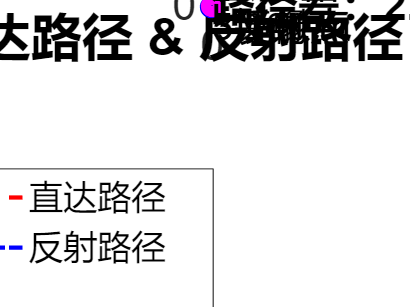


% ===== 可视化 =====
figure; hold on; grid on;
axis equal;
set(gca, 'FontSize', 20);
xlabel('X-axis (m)', 'FontSize', 22, 'Color', 'k'); 
ylabel('Y-axis (m)', 'FontSize', 22, 'Color', 'k');
title('直达路径 & 反射路径', 'FontSize', 24, 'FontWeight', 'bold', 'Color', 'k');

% 墙面和原点
plot([-2, 2], [0, 0], 'k', 'LineWidth', 2);
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% 发射与接收端
plot(x1, y1, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(x2, y2, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
text(x1, y1, '  Tx', 'FontSize', 20, 'Color', 'k', 'VerticalAlignment', 'bottom');
text(x2, y2, '  Rx', 'FontSize', 20, 'Color', 'k', 'VerticalAlignment', 'bottom');

% 绘制天线朝向箭头
quiver(x1, y1, tx_dir(1), tx_dir(2), 0.6, 'r', 'LineWidth', 2, 'MaxHeadSize', 2);
quiver(x2, y2, rx_dir(1), rx_dir(2), 0.6, 'b', 'LineWidth', 2, 'MaxHeadSize', 2);

% 直达路径
plot([x1, x2], [y1, y2], 'r--', 'LineWidth', 2);
text(mean([x1, x2]), mean([y1, y2]), ...
    sprintf(' 直达路径\n %.3f m', direct_path), 'FontSize', 18, 'Color', 'k');

% 反射路径
plot([x1_mirror, x2], [y1_mirror, y2], 'b-.', 'LineWidth', 2);
plot(x1_mirror, y1_mirror, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');
text(x1_mirror, y1_mirror, '  镜像点', 'FontSize', 18, 'Color', 'k', 'VerticalAlignment', 'top');
text(mean([x1_mirror, x2]), mean([y1_mirror, y2]), ...
    sprintf(' 反射路径\n %.3f m', reflected_path), 'FontSize', 18, 'Color', 'k');

% 显示路径差信息
text(0, -2.4, sprintf('路径差：%.4f m', path_diff), ...
    'FontSize', 20, 'FontWeight', 'bold', 'Color', 'k');

legend({'墙面 (x轴)', '原点 (0,0)', '发射端 Tx', '接收端 Rx', ...
        'Tx天线方向', 'Rx天线方向', '直达路径', '反射路径', '镜像点'}, ...
       'Location', 'SouthOutside', 'NumColumns', 3, 'FontSize', 16, 'TextColor', 'k');

hold off;

rad2deg(atan(2/2.4))